## 5.4.1 Exercise

### PROBLEM 6


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\overset{\ldotp }{x_1 } \\
\overset{\ldotp }{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
23 & 13\\
-45 & -25
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
-1\\
2
\end{array}\right\rbrack u\;\;\\
\mathrm{and}\\
y\;=\left\lbrack \begin{array}{cc}
5 & 3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \;
\end{array}$$


Using the above we will find the transfer function 

3) Find the transfer function G(s) (doing this part of the problem first for convenience)

clear all; close all; clc;

% Assign the space state realization matrices 
a = [23 13; -45 -25];
b = [-1; 2];
c = [5 3]; 
d = 0

d = 0


% Convert the space state into transfer function 
[num, den] = ss2tf(a, b, c, d);
% From the numerator and denominator expression construct the tf
g = tf(num, den);


g =
 
      s + 2
  --------------
  s^2 + 2 s + 10
 
Continuous-time transfer function.



1) if u(t) = 60, then compute y(inf) = lim(t->inf) y(t)

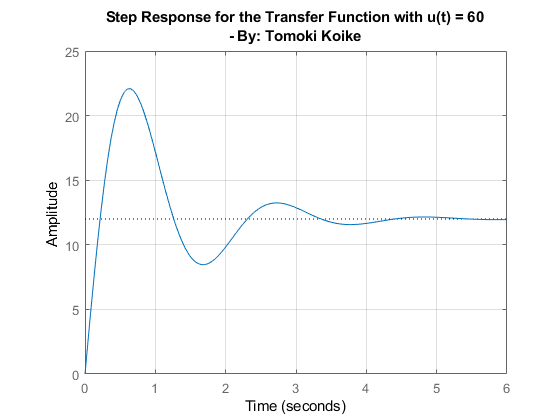

u_o = 60;
% Plotting 
figure(1)
step(g*u_o);
title({'Step Response for the Transfer Function with u(t) = 60', ['' ...
    '- By: Tomoki Koike']})
grid on
grid minor
box on


% Computing the infinite limit for y(inf)
y_inf = -c * inv(a) * b * u_o;
fprintf('y(inf) equals: %.1f', y_inf);

y(inf) equals: 12.0

2) Graph the output y(t) for u(t) = 60

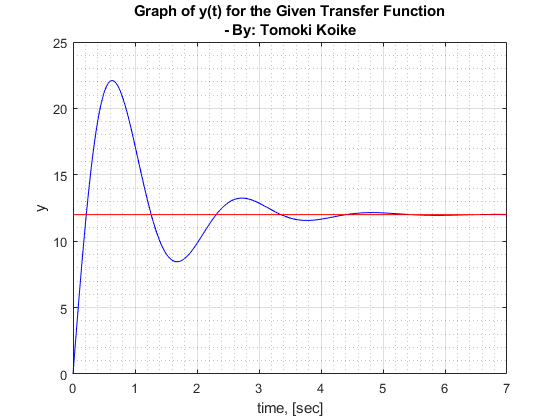

% Figuring out the y equation 
[r, p] = residue(60*[1, 2], [1, 2, 10, 0]);  % Obtaining the residues and poles
% Constructing the y function
t = 0:0.01:7;
y = 12 + -12*exp(-t).*cos(3*t) + 16*exp(-t).*sin(3*t);

% Plotting 
figure(2)
plot(t, y,'b')
title({'Graph of y(t) for the Given Transfer Function', ['' ...
    '- By: Tomoki Koike']})
xlabel('time, [sec]')
ylabel('y')
hold on
plot(t, repmat(12,length(t),1), '-r')
hold off
grid on 
grid minor
box on

4) Find the McMillan Degree

fprintf('The McMillan degree for this transfer function is: 2');

5) Is the space state realization for this transfer function the minimal realization?

g_min = minreal(g);
[A,B,C,D] = tf2ss([0,1,2], [1,2,10]);
fprintf('--Space State Realizaiton--')

--Space State Realizaiton--

fprintf('>>A')

>>A

disp(A);

    -2   -10
     1     0



fprintf('>>B')

>>B

disp(B);

     1
     0



fprintf('>>C')

>>C

disp(C);

     1     2



fprintf('>>D')

>>D

disp(D);

     0

